# Wind Energy

wind_data = readtable("monkey-data/wind.csv")

wind_data = 8760×7 table
    YEAR    MO    DY    HR    WD10M     WS10M      PS  
    ____    __    __    __    ______    _____    ______

    2023    1     1      0    356.39     3.6     102.68
    2023    1     1      1    351.54    3.03     102.67
    2023    1     1      2    342.66    2.73     102.67
    2023    1     1      3    336.16    2.94     102.67
    2023    1     1      4     332.9    3.02     102.67
    2023    1     1      5    326.66    2.46     102.66
    2023    1     1      6    320.45    2.21      102.7
    2023    1     1      7    317.22    2.28     102.75
    2023    1     1      8    307.38    2.12      102.8
    2023    1     1      9    276.21    1.95     102.82
    2023    1     1     10    272.61     2.4     102.87
    2023

wind_data.time = datetime(wind_data.YEAR, wind_data.MO, wind_data.DY, wind_data.HR, 0, 0);
%Wind Direction
mean_dir = mean(wind_data.WD10M)

mean_dir = 186.7058

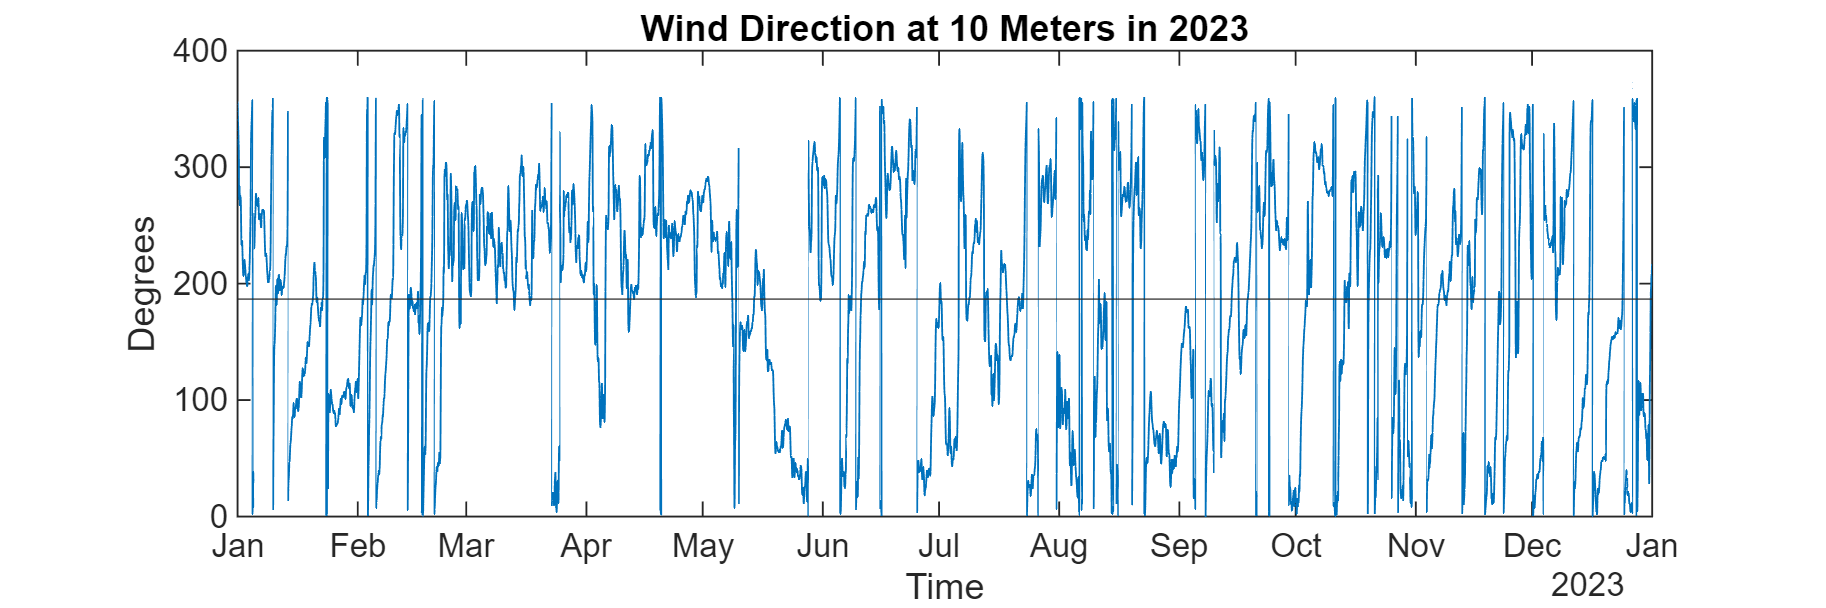

%yearly
figure;
plot(wind_data.time, wind_data.WD10M);
set(gcf, 'Position', [100, 100, 1200, 400]); 
xlabel('Time');
ylabel('Degrees');
yline(mean_dir);
title('Wind Direction at 10 Meters in 2023');

% Wind Direction
mean_dir = mean(wind_data.WD10M);
max_dir = max(wind_data.WD10M);
min_dir = min(wind_data.WD10M);

% Wind Speed
mean_sp = mean(wind_data.WS10M);
max_sp = max(wind_data.WS10M);
min_sp = min(wind_data.WS10M);

% Display statistics
fprintf('Wind Direction: Mean = %.2f°, Max = %.2f°, Min = %.2f°\n', mean_dir, max_dir, min_dir);

Wind Direction: Mean = 186.71°, Max = 359.95°, Min = 0.00°


fprintf('Wind Speed: Mean = %.2f m/s, Max = %.2f m/s, Min = %.2f m/s\n', mean_sp, max_sp, min_sp);

Wind Speed: Mean = 6.92 m/s, Max = 29.22 m/s, Min = 0.06 m/s


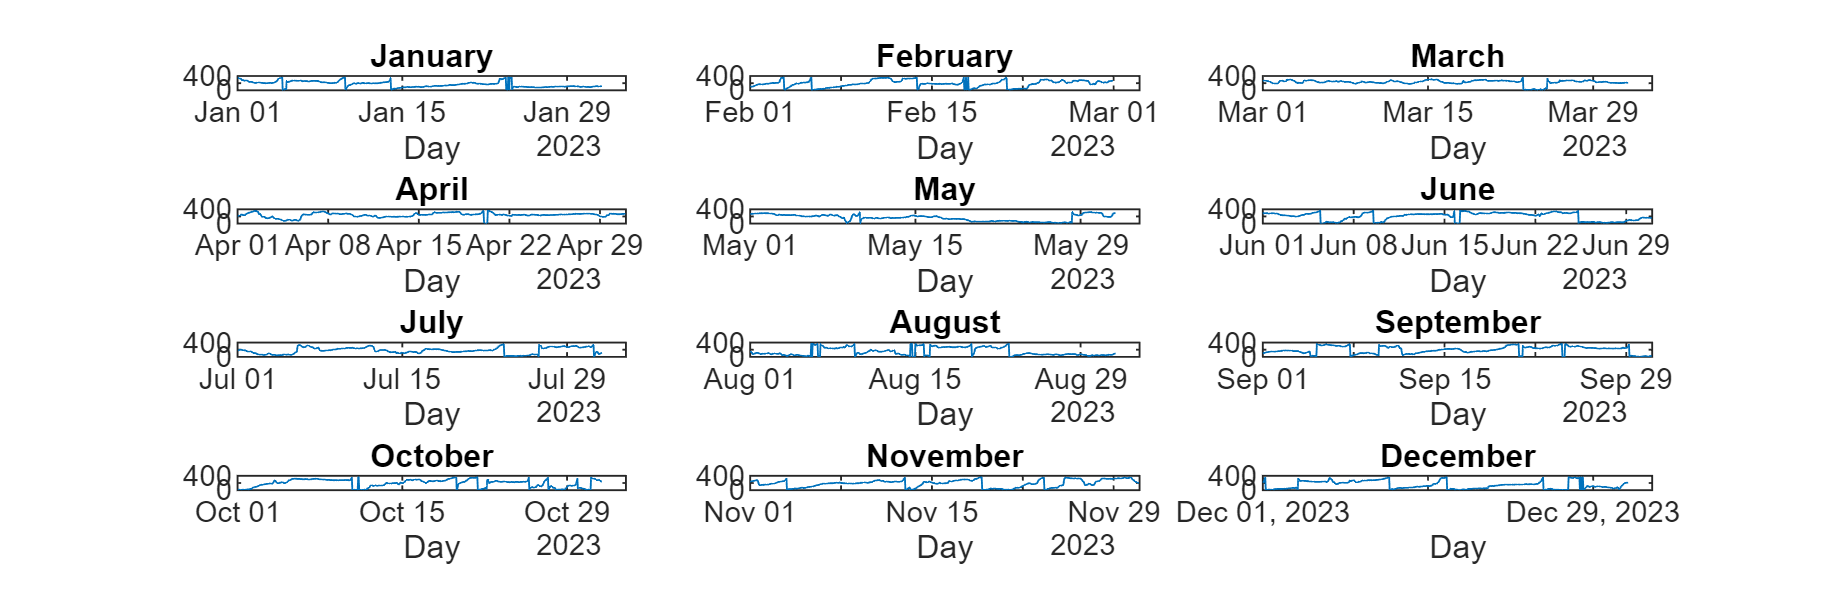

%monthly
figure;
months_name = ["January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];
for month = 1:12
    set(gcf, 'Position', [100, 100, 1200, 400]); 
    subplot(4, 3, month); 
    month_data = wind_data(wind_data.MO == month, :); 
    plot(month_data.time, month_data.WD10M);
    title(months_name(month));
    xlabel('Day');
    ylabel('Degrees');
end

%Wind speed
mean_sp = mean(wind_data.WS10M)

mean_sp = 6.9192

mean_sp

mean_sp = 6.9192

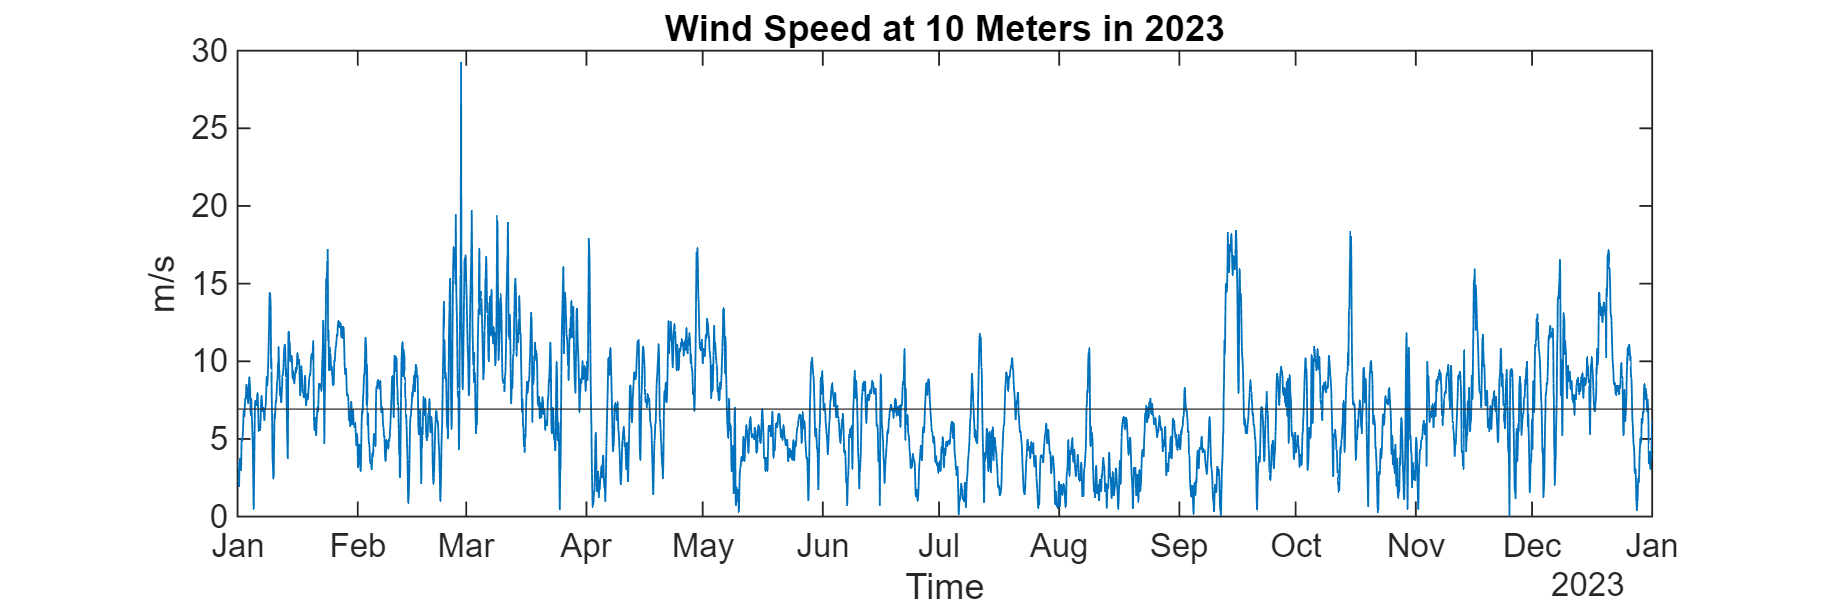

%yearly
figure;
plot(wind_data.time, wind_data.WS10M);
set(gcf, 'Position', [100, 100, 1200, 400]); 
xlabel('Time');
ylabel('m/s');
yline(mean_sp);
title('Wind Speed at 10 Meters in 2023');

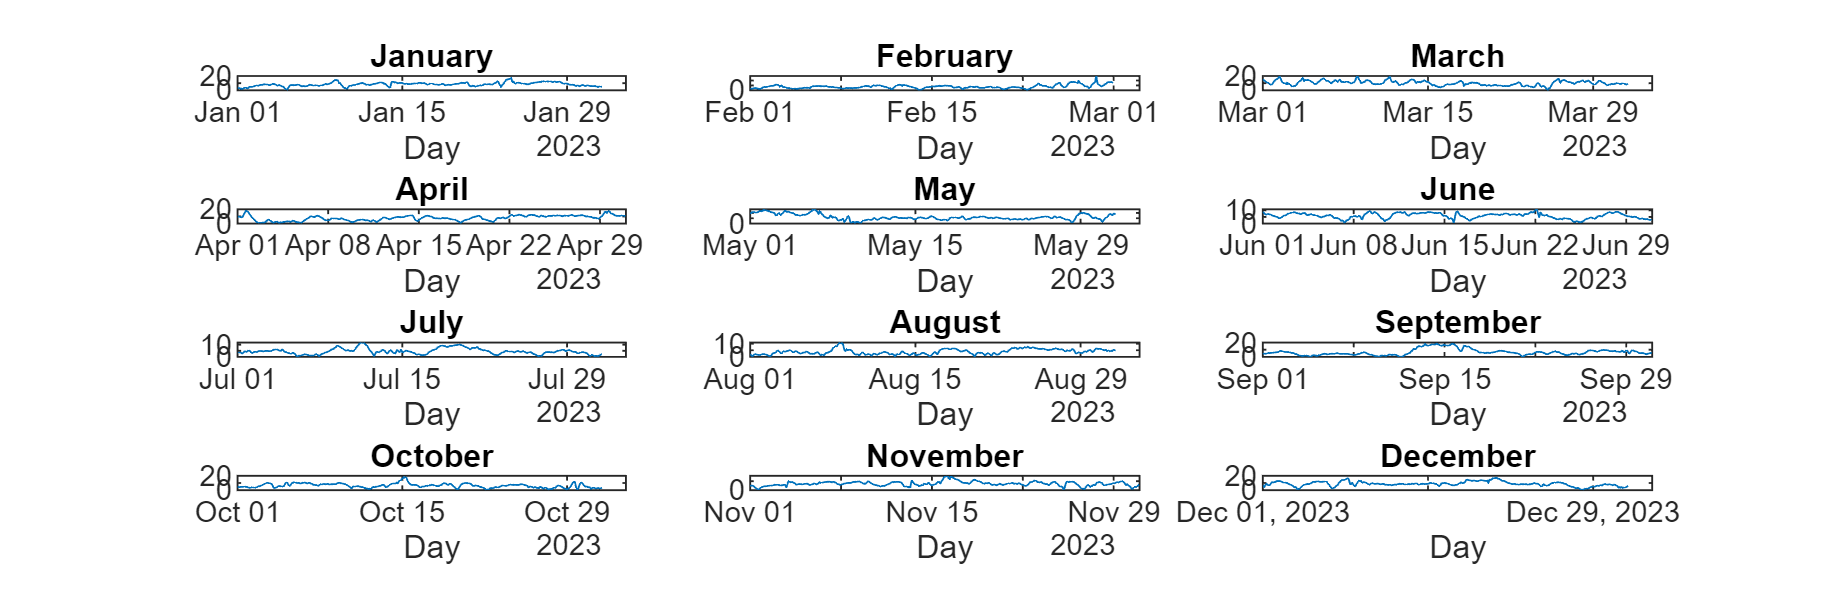

%monthly
figure;
months_name = ["January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];
for month = 1:12
    set(gcf, 'Position', [100, 100, 1200, 400]); 
    subplot(4, 3, month); 
    month_data = wind_data(wind_data.MO == month, :); 
    plot(month_data.time, month_data.WS10M);
    title(months_name(month));
    xlabel('Day');
    ylabel('m/s');

end

%turbines


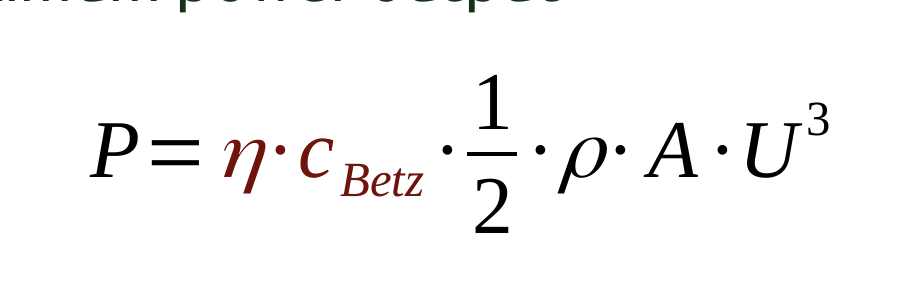

%air density (to delete ?)

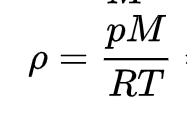

M = 0.029;
R = 8.314;
%check temperature
T = 19;
air_density = ((wind_data.PS) .* M) ./ (R * T);
Cbetz = 0.59;

%10 kW Senhui vertical axis turbine 

power_output_10kW = [0, 0, 0, 0, 0.4, 1, 1.8, 2.8, 3.6, 5.2, 6.8, 8.2, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 8.5, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0]

power_output_10kW =          0         0         0         0    0.4000    1.0000    1.8000    2.8000    3.6000    5.2000    6.8000    8.2000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000    8.5000         0         0         0         0         0         0         0         0         0         0


power_output_20kW = [0, 0, 0, 0, 1.2, 3, 5.5, 9, 14, 19.5, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 17]

power_output_20kW =          0         0         0         0    1.2000    3.0000    5.5000    9.0000   14.0000   19.5000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   17.0000


power_output_30kW = [0, 0, 0, 0, 0.48, 1.68, 3, 4.8, 7.2, 10.2, 13.5, 18.75, 27.9, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 30, 25.5]

power_output_30kW =          0         0         0         0    0.4800    1.6800    3.0000    4.8000    7.2000   10.2000   13.5000   18.7500   27.9000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   25.5000


%%faire des cas par éolienne
%%calculer les puissance
%%tracer sur les graphes

power_10kW = zeros(size(wind_data.WS10M));
power_20kW = zeros(size(wind_data.WS10M));
power_30kW = zeros(size(wind_data.WS10M));

% Boucle simple pour associer chaque vitesse du vent à la puissance
for i = 1:length(wind_data.WS10M)
    wind_speed = int8(wind_data.WS10M(i));

    if wind_speed >= 3 && wind_speed <= 35
        power_10kW(i) = power_output_10kW(wind_speed + 1); 
        power_20kW(i) = power_output_20kW(wind_speed + 1); 
        power_30kW(i) = power_output_30kW(wind_speed + 1);
    end
end
hold off;

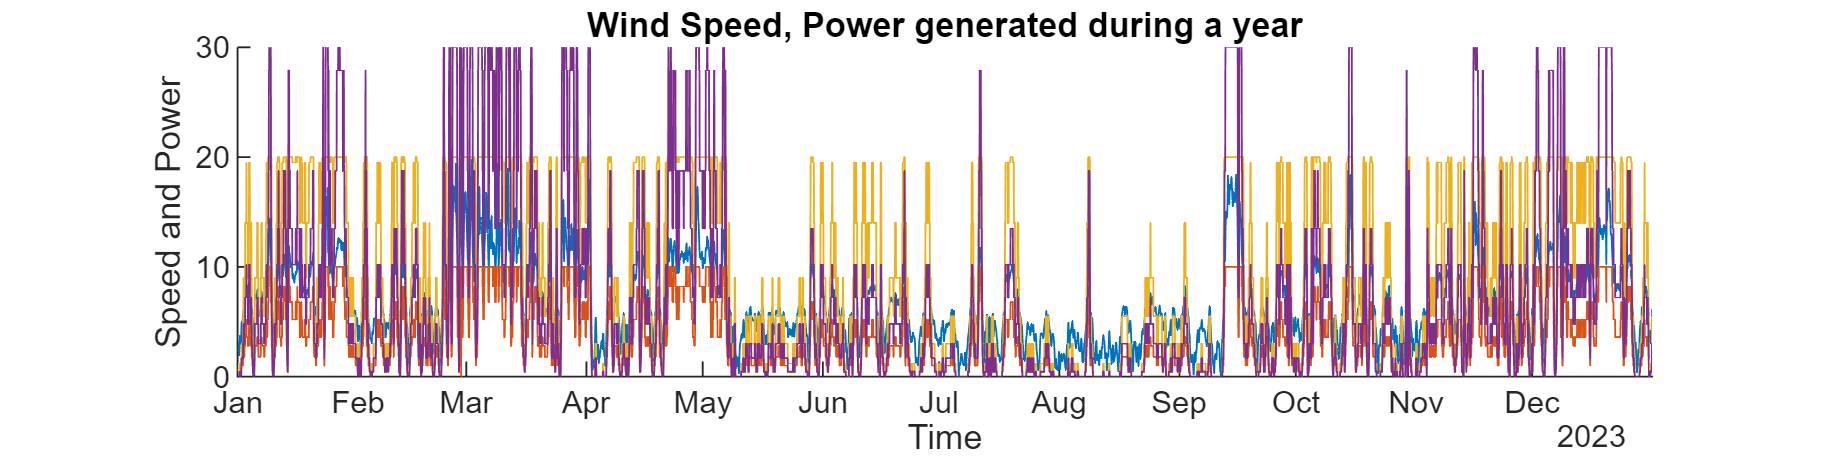

figure;
hold on;
plot(wind_data.time, wind_data.WS10M);
set(gcf, 'Position', [100, 100, 1600, 400]); 
xlabel('Time');
ylabel('Speed and Power');
title('Wind Speed, Power generated during a year');
xlim([wind_data.time(1), wind_data.time(8760)]);
plot(wind_data.time, power_10kW)
plot(wind_data.time, power_20kW)
plot(wind_data.time, power_30kW)
hold off

% Calcul des statistiques de puissance
total_power_10kW = sum(power_10kW);
total_power_20kW = sum(power_20kW);
total_power_30kW = sum(power_30kW);

max_power_10kW = max(power_10kW);
min_power_10kW = min(power_10kW);
mean_power_10kW = mean(power_10kW);

max_power_20kW = max(power_20kW);
min_power_20kW = min(power_20kW);
mean_power_20kW = mean(power_20kW);

max_power_30kW = max(power_30kW);
min_power_30kW = min(power_30kW);
mean_power_30kW = mean(power_30kW);

% Affichage des statistiques
fprintf('10kW Turbine: Total = %.2f kWh, Mean = %.2f kW, Max = %.2f kW, Min = %.2f kW\n', total_power_10kW, mean_power_10kW, max_power_10kW, min_power_10kW);

10kW Turbine: Total = 28873.70 kWh, Mean = 3.30 kW, Max = 10.00 kW, Min = 0.00 kW


fprintf('20kW Turbine: Total = %.2f kWh, Mean = %.2f kW, Max = %.2f kW, Min = %.2f kW\n', total_power_20kW, mean_power_20kW, max_power_20kW, min_power_20kW);

20kW Turbine: Total = 83078.40 kWh, Mean = 9.48 kW, Max = 20.00 kW, Min = 0.00 kW


fprintf('30kW Turbine: Total = %.2f kWh, Mean = %.2f kW, Max = %.2f kW, Min = %.2f kW\n', total_power_30kW, mean_power_30kW, max_power_30kW, min_power_30kW);

30kW Turbine: Total = 64352.76 kWh, Mean = 7.35 kW, Max = 30.00 kW, Min = 0.00 kW
